## TOPIC 24: Symbolic variables, equations, and functions

ENGR105, 11/24/20

**Note**: for these notes, you will need the `Symbolic Math Toolbox` installed. 

### Symbolic math in MATLAB

- According to Mathworks, LiveScript documents are the recommended documents for performing symbolic operations. 

- Symbolic math in MATLAB is based on the MuPAD computational engine.

- [Reference documentation on changing output from symbolic operations](https://www.mathworks.com/help/symbolic/modify-output-of-symbolic-results.html)

- `help symbolic` for MATLAB help documentation

In addtion to its capabilities with numerical processing, MATLAB provides built-in capabilities for solving, plotting, and manipulating symbolic math equations. **A main difference** between data types `symbolic` and `double` is that symbolic numbers are **exact**, whereas double values have **floating point precision** (see Lecture 15 / Topic 14). 

**Example**. Calculate $\sin \left(\pi \right)$

% Using the numerical calculation, as before
sin(pi)

ans = 1.2246e-16

% Using symbolic
sin(sym(pi))

$$ans = 0$$

Here, we create a *symbolic number *by using `sym`.

**Important note**: while the numeric calculation does not return the exact result, it much more accurate than what we typically "need."

#### Declaring symbolic numbers and variables

You can create symbolic variables by using either `syms` or `sym`, or by assigning the **output from a symbolic expression** to a new variable.

- `syms` - use `syms` to symbolic **variables** that can be manipulated in symbolic expressions.

% Declare symbolic variables
syms x y
% Inspect properties of variables
whos x y

  Name      Size            Bytes  Class    Attributes

  x         1x1                 8  sym                
  y         1x1                 8  sym                



- `sym` – use `sym` to create **symbolic numbers**

% Create symbolic numbers
sym(5)

$$ans = 5$$

sym(pi)

$$ans = \pi$$

sym(sqrt(2))

$$ans = \sqrt{2}$$

1+sym(pi)

$$ans = \pi +1$$

**Note**: use sym on the "innermost" number only to create an exact number. Otherwise, the sym operator will be applied to the product of a floating point (numerical) operation.

% Correct: convert pi to symbolic, then operate on it.
sqrt(sym(pi))

$$ans = \sqrt{\pi }$$

% Incorrect: Convert the output from sqrt(pi) to a symbolic representation
sym(sqrt(pi))

$$ans = \frac{3991211251234741}{2251799813685248}$$

- Assign an output from symbolic manipulations to a new variable.

% Create symbolic variable phi, also known as the "golden ratio"
phi = (1 + sqrt(sym(5)))/2

$$phi = \frac{\sqrt{5}}{2}+\frac{1}{2}$$

**Note**: a symbolic number can be converted to double by using the `double` command

% Convert symbolic to double
double(phi)

ans = 1.6180

#### Symbolic expressions and functions

The above variable, phi, is created using a symbolic expression. You can now perform subsequent operations on `phi`.

% Operation 1
f1 = phi^2 - phi - 1

$$f1 = {\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{2}-\frac{\sqrt{5}}{2}-\frac{3}{2}$$

% Operation 2
f2 = phi^2 + 1

$$f2 = {\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{2}+1$$

**Simplifying expressions**. Use `simplify` to simplify an expression

% Simplify f1
simplify(f1)

$$ans = 0$$

% Simplify f2
simplify(f2)

$$ans = \frac{\sqrt{5}}{2}+\frac{5}{2}$$

**Symbolic expressions with symbolic variables** are useful when you wish to perform mathematical manipulations on an equation.

% Create original equation
syms x
g = x^3 + 6*x^2 + 11*x + 6

$$g = x^{3}+6\,x^{2}+11\,x+6$$


% Manipulate equation by dividing it by (x+3)
g2 = g/(x+3)

$$g2 = \frac{x^{3}+6\,x^{2}+11\,x+6}{x+3}$$

% Simplify equation
g2 = simplify(g2)

$$g2 = x^{2}+3\,x+2$$

**Note**: to substitute a number in for a variable, you must use the `subs` command

% Parenthesis cannot be used to substitute for a variable
g2(1)

$$ans = x^{2}+3\,x+2$$

% Instead, use subs to evaluate for particular values
subs(g2,x,1)

$$ans = 6$$

% Note: the original equation is unchanged
g2

$$g2 = x^{2}+3\,x+2$$

**Symbolic functions**. If you intend to perform repeated evaluations, create a **symbolic function** instead. This can be declared using the syms function.

clear
syms f(x)
% Specify function. NOTE: must define f(x)
f(x) = x^2-1+sqrt(sym(pi));
% the function f(x) will be displayed if either f or f(x) is called
disp(f(x))

$$x^{2}+\sqrt{\pi }-1$$

disp(f)

$$x^{2}+\sqrt{\pi }-1$$

% In this case, direct substitution can occur with parenthesis
f(1)

$$ans = \sqrt{\pi }$$

f(2)

$$ans = \sqrt{\pi }+3$$

#### Plotting symbolic functions

**Plot symbolic equations using **`fplot`. The most common method for plotting symbolic functions is to use` fplot()`. `fplot()` takes the following inputs: 

- *First input*: function to be plotted

- *Second input*: time domain,

- *Third input*: line specifications

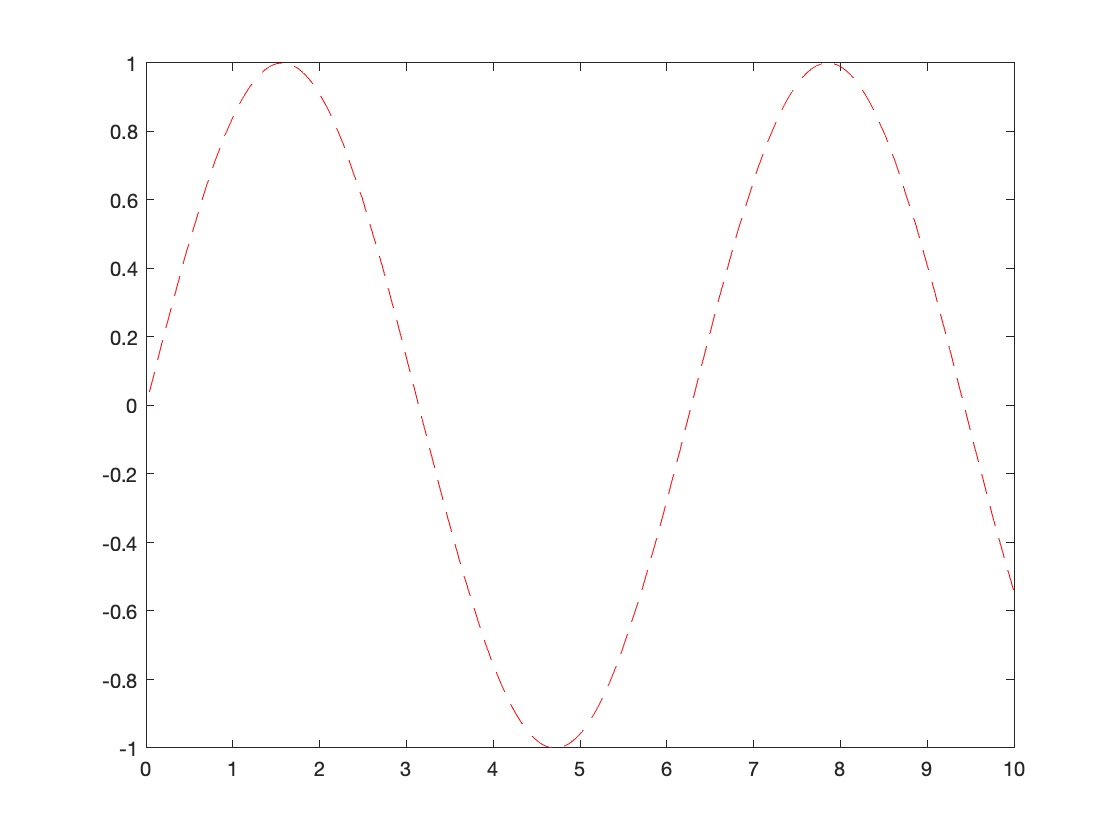

clear
% Declare symbolic variables
syms x
% Plot sin(x) over the domain [0,10]
fplot(sin(x), [0,10], 'r--')

Plots of symbolic functions can also be modified as **graphics handle objects**.

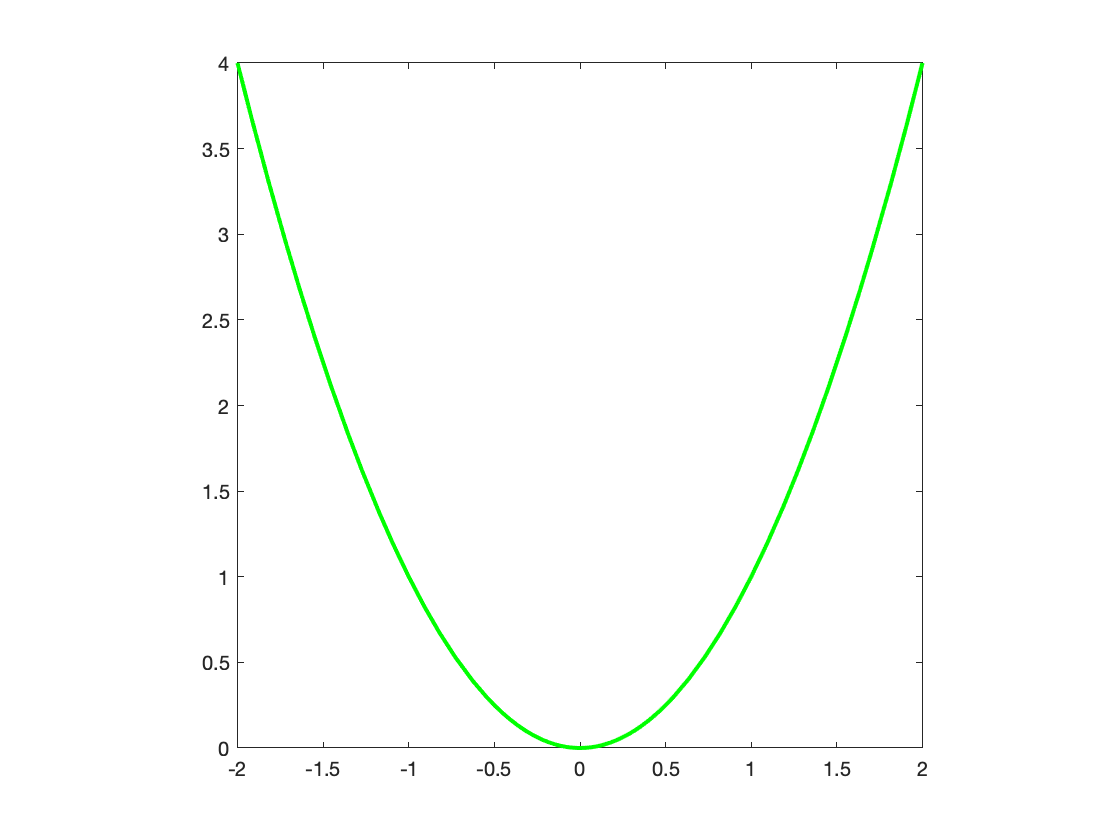

% Declare symbolic variable
syms t

% Plot function and specify parameters
h1 = fplot(t^2,[-2,2]);
h1.LineWidth = 2;
h1.Color = 'g';
axis square

**Important note**: symbolic functions are **not** plotted with infinite precision. When you plot a symbolic function, the following happens:

- MATLAB automatically **creates vectors of x and y data** spanning the specified domain.

- MATLAB **plots those two vectors** and assigns the specified formatting.

The x and y data that is created can be accessed using the graphics handle object.

% Acquire data vectors that were plotted to create the above plot.
xdata = h1.XData;
ydata = h1.YData;

Thus, you could produce an **equivalent plot** using the standard `plot() `function.

% Equivalent plot
plot(xdata,ydata,'g-','LineWidth',2)
axis square

**Note****:** you can also plot **anonymous functions** using `fplot`.

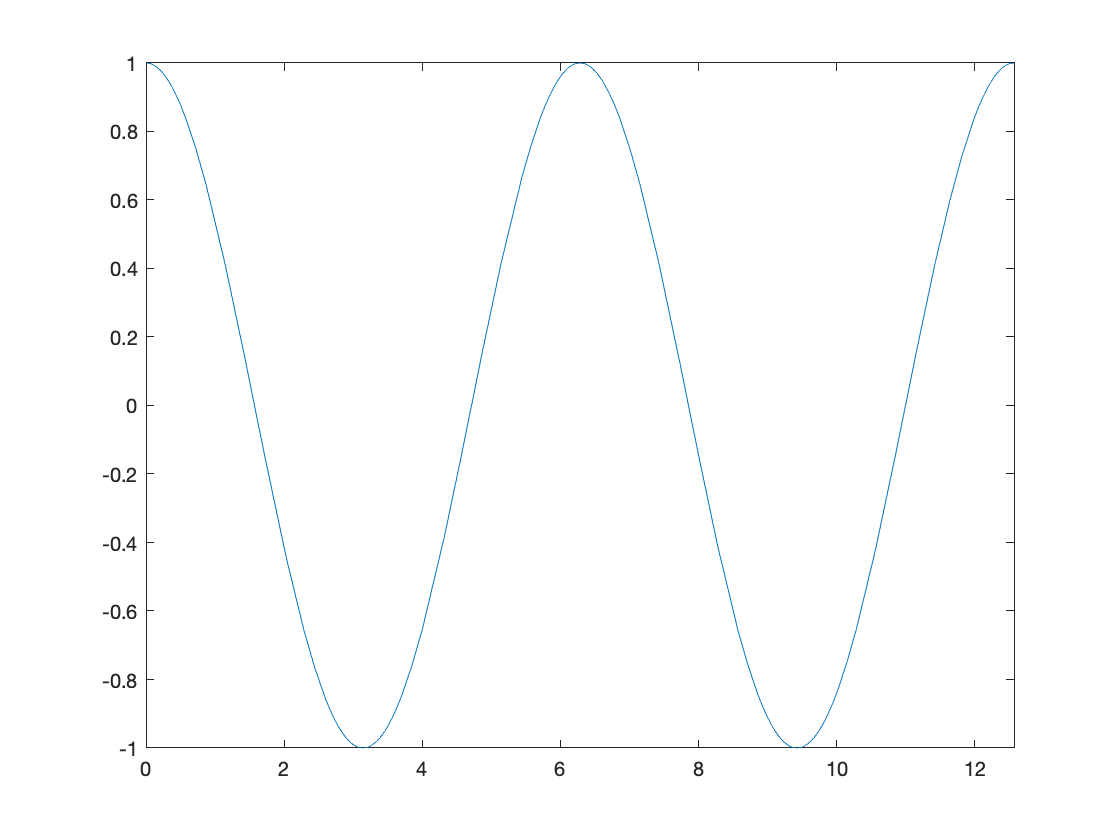

clear
% Produce a plot of cos(x) between 0 and 4*pi
fplot(@(x) cos(x),[0,4*pi])

**Plot symbolic equations in 3D using **`fplot3`. The symbolic analog to` plot3()` is `fplot3()`, which can be used to plot parametric curves. 

**Example**. plot the curve given by $x\left(t\right)=t,\;y\left(t\right)=\sin \left(t\right),\;z\left(t\right)=\cos \left(t\right)$ for $t\in \left\lbrack -10,10\right\rbrack$

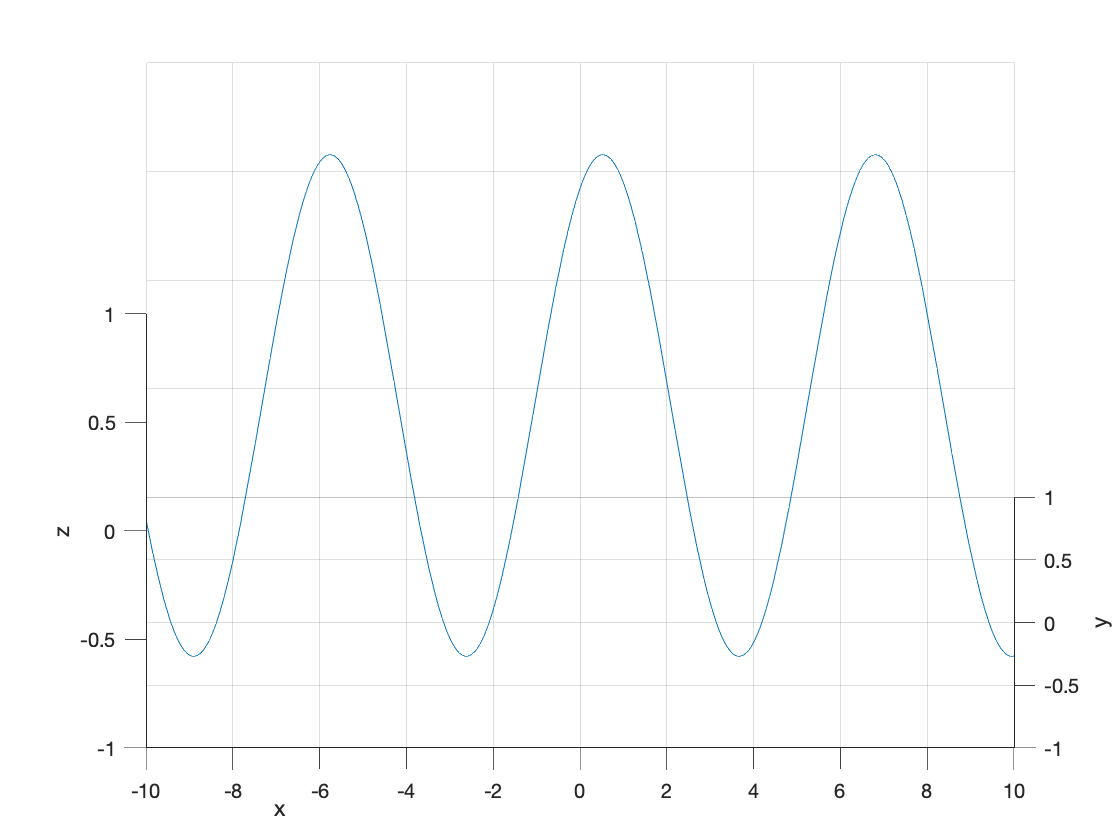

% Declare symbolic variable
syms t
% Produce a 3D plot corresponding to the above
fplot3(t,sin(t),cos(t),[-10,10])
xlabel('x')
ylabel('y')
zlabel('z')

% Add constant rotation to the plot
for k = 1:360
    % Update the view point
    view(k,30)
    % Pause MATLAB for 100 ms
    pause(0.1)
end

**Plot implicit relationships using **`fimplicit`. When you cannot easily solve for one variable in terms of another, you can plot the implicit form of the relationship.

**Example**. Plot $1=y^2 +x$

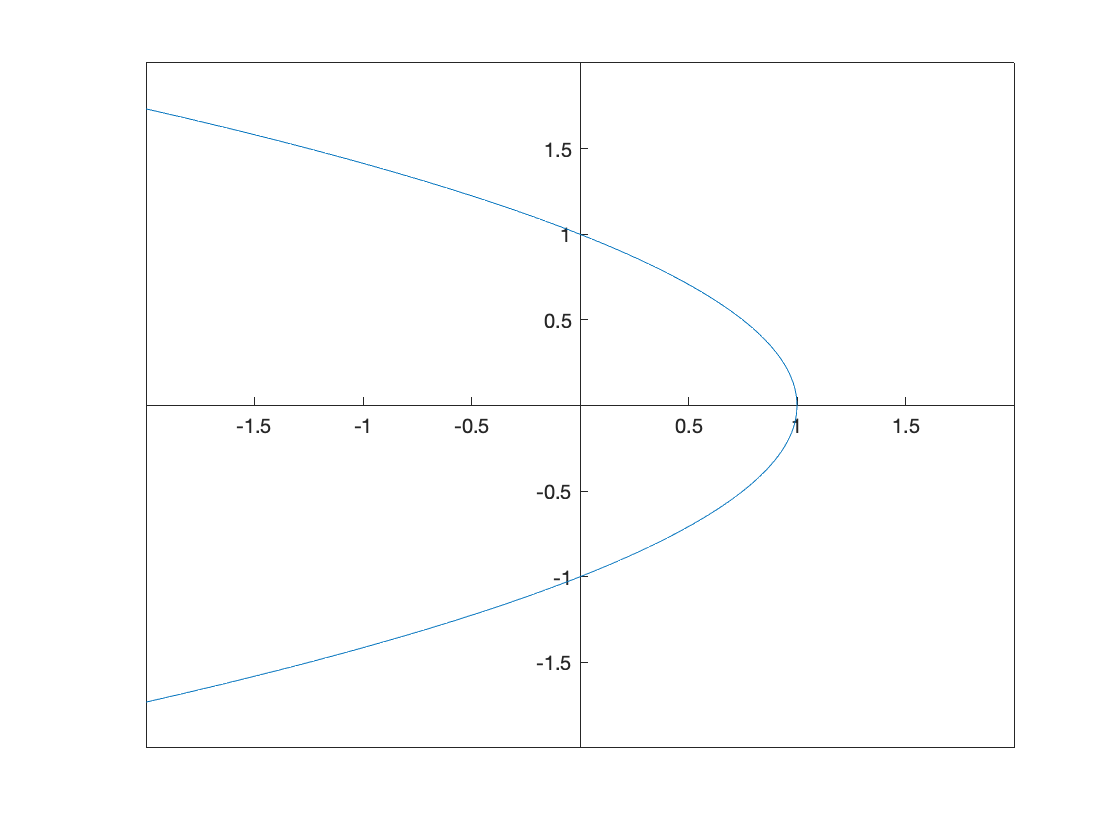

syms x y
fimplicit(1==y^2+x,[-2,2])
set(gca,'XAxisLocation','Origin')
set(gca,'YAxisLocation','Origin')

**Notes:**

- The variable that comes **first** in alphanumeric order is assigned to the **x variable**.

- The above example specifies the **x domain** to be plotted over.

#### Solving equations of one variable

Exact solutions to an equation may be obtained using the `solve()` function. 

clear
syms x   % Declare symbolic variable
% Example 1
solve(5*x == 1)

$$ans = \frac{1}{5}$$

% Example 2: multiple solutions are present
solve(x^2 - 1 == 0)

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

% Example 3: can obtain complex solutions
solve(x^2 + 1 == 0)

$$ans = \left(\begin{array}{c} -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

#### Solving sets of linear equations

Consider the system of two equations used previously in Lecture 4:

                        
$$\begin{array}{l}
y=x\\
y=2x-3
\end{array}$$


**To solve the set of equation,** each equation can be assigned to a symbolic variable.

clear
syms x y % declare variables as symbolic
eqn1 = y==2*x-3;    % first equation
eqn2 = y==x;    % second equation

**Note:** the double equals (`==`) says that two symbolic expression are equal to one another.

Use `solve()` to determine the **solution to the system of equations**. In this case, the output `res` is a data structure. The "`.x`" and "`.y`" are simply used to call the solution value to each variable.

res = solve([eqn1,eqn2],[x,y]);
xSol = res.x % retrieve the x solution

$$xSol = 3$$

ySol = res.y % retrieve the y solution

$$ySol = 3$$

**Comparison to linear algebra**. Consider the set of linear equations from **example 2 **in** Lecture 3 / Topic 4. **

                
$$\begin{array}{l}
x_1 +{3x}_2 +x_3 =1\\
{2x}_1 +{2x}_2 -x_3 =2\\
x_1 +x_2 +x_3 =-2
\end{array}$$


Solve the following system of equations using symbolics and linear algebra.

**1) Using symbolic variables**

tic
syms x1 x2 x3
% Define equations
eqn1 = x1 + 3*x2 + x3 == 1;
eqn2 = 2*x1 + 2*x2 - x3 == 2;
eqn3 = x1 + x2 + x3 == -2;
% Solve set of linear equations
res = solve([eqn1,eqn2,eqn3],[x1,x2,x3]);
% Display the solution for each variable
disp(res.x1)

$$-\frac{3}{2}$$

disp(res.x2)

$$\frac{3}{2}$$

disp(res.x3)

$$-2$$

toc

Elapsed time is 0.161226 seconds.


**2) Using linear algebra**

tic
% Step 1: convert to matrix format
A = [1,3,1;2,2,-1;1,1,1]; %Coefficient matrix defined above
b = [1;2;-2]; % Constant matrix
% Step 2: solve for x 
x = A\b

x =    -1.5000
    1.5000
   -2.0000


toc

Elapsed time is 0.008197 seconds.


**Takeaway**: both work fine, but even for this *simple* set of 3 equations, the linear algebra approach is quicker by 1-2 orders of magnitude! **You will have to use linear algebra to solve large sets of equations**.

#### Solving sets of nonlinear equations

Sets of (simple) nonlinear equations can also be readily solved using the `solve()` function. Consider the following set of equations:

                        
$$\begin{array}{l}
y^2 =x\\
y=2x-3
\end{array}$$


Especially when solving sets of nonlinear equations, it is advisable to plot them to get an idea of where the solutions should be.

- Use `fimplicit()` to plot symbolic equations in the form we defined above.

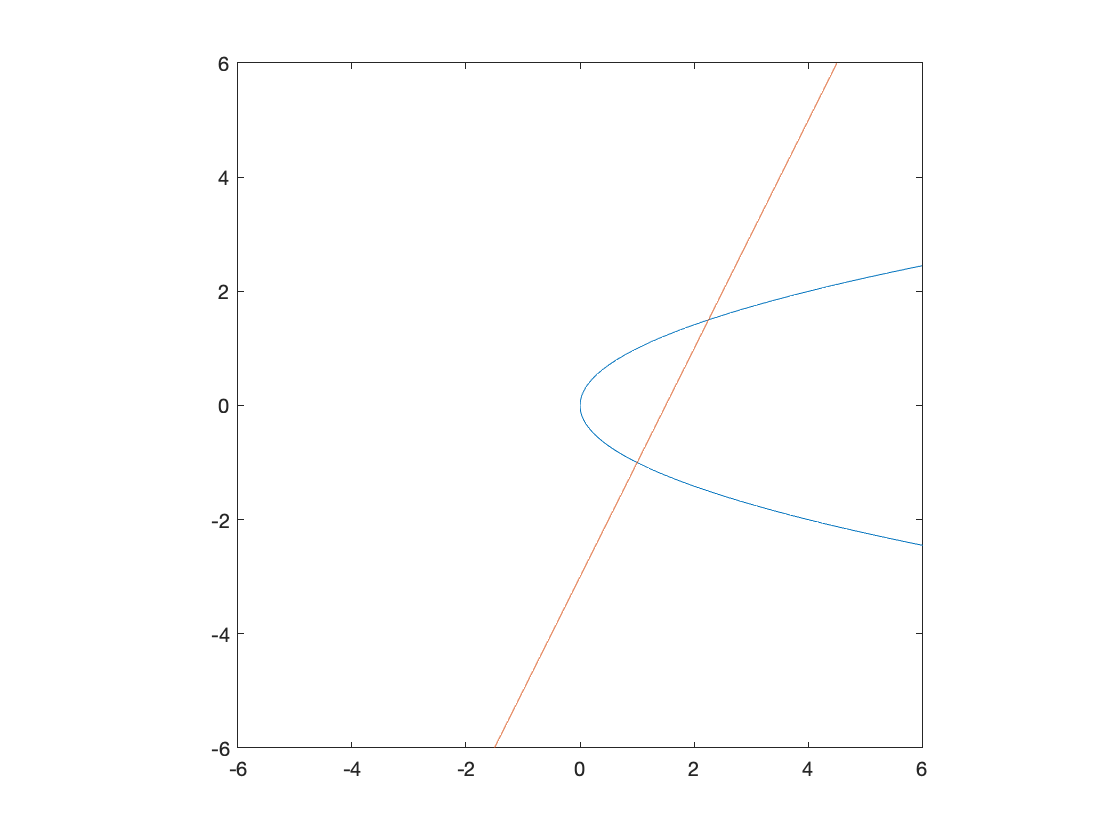

% Declare variables and equations
syms x y 
eqn1 = y^2==x;
eqn2 = y==2*x-3;
% Plot equations on the interval for x and y of [-6,6]
fimplicit([eqn1,eqn2],[-6,6,-6,6])
axis square

- As before, we can solve the system of equations using `solve()`.

% Solve system of nonlinear equations
res2 = solve([eqn1,eqn2],[x,y]);
xSol2 = res2.x % retrieve the x solution

$$xSol2 = \left(\begin{array}{c} 1\\ \frac{9}{4} \end{array}\right)$$

ySol2 = res2.y % retrieve the y solution

$$ySol2 = \left(\begin{array}{c} -1\\ \frac{3}{2} \end{array}\right)$$

**Comparison to numerically solving**. Consider the following, slightly more nonlinear set of equations. We can plot it by running the same code as before.

                        
$$\begin{array}{l}
y^2 =x\\
y=2x^2 -3
\end{array}$$


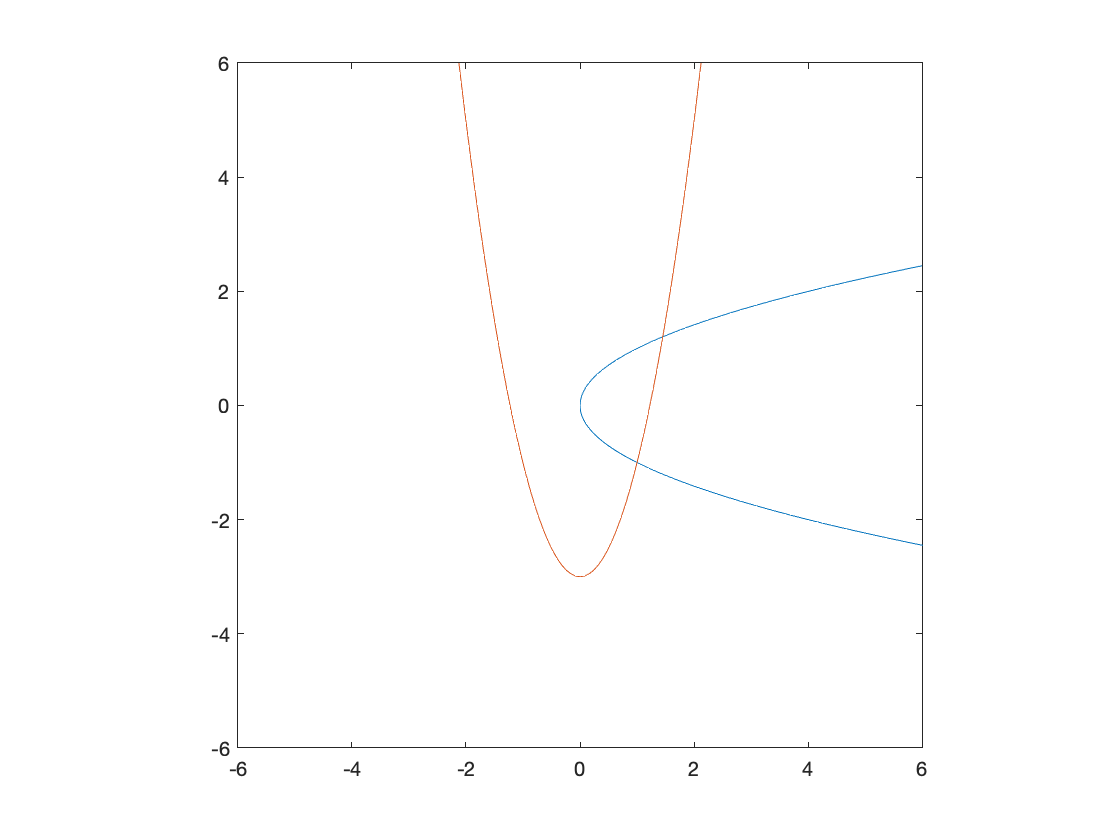

% Declare variables and equations
syms x y 
eqn1 = y^2==x;
eqn2 = y==2*x^2-3;
% Plot equations on the interval for x and y of [-6,6]
fimplicit([eqn1,eqn2],[-6,6,-6,6])
axis square

**1) Solve using symbolic math**

% Solve system of nonlinear equations
res3 = solve([eqn1,eqn2],[x,y]);
xSol3 = res3.x % retrieve the x solution

$$xSol3 = \left(\begin{array}{c} 1\\ {\mathrm{root}\left(z^{3}-z^{2}+z-\frac{3}{2},z,1\right)}^{2}\\ {\mathrm{root}\left(z^{3}-z^{2}+z-\frac{3}{2},z,2\right)}^{2}\\ {\mathrm{root}\left(z^{3}-z^{2}+z-\frac{3}{2},z,3\right)}^{2} \end{array}\right)$$

ySol3 = res3.y % retrieve the y solution

$$ySol3 = \left(\begin{array}{c} -1\\ \mathrm{root}\left(z^{3}-z^{2}+z-\frac{3}{2},z,1\right)\\ \mathrm{root}\left(z^{3}-z^{2}+z-\frac{3}{2},z,2\right)\\ \mathrm{root}\left(z^{3}-z^{2}+z-\frac{3}{2},z,3\right) \end{array}\right)$$

The solver returns the **exact** solution, which isn't necessarily useful.

**2) Solve using numerical method. **Using `fsolve` as before, we can solve this set of nonlinear equations.

% Determine solution 1
sol_1 = fsolve(@eqnSet,[0,0]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


% Determine solution 2
sol_2 = fsolve(@eqnSet,[1,1]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


disp(sol_1)

    1.0000   -1.0000



disp(sol_2)

    1.4498    1.2041



**Takeaway**: `solve()` is trying to find an exact solution, which is not always very useful. Often a numerical solution is *more than accurate enough* for a given application.

**For more information** on modifying outputs from symbolic manipulations, see the [reference documentation from MATLAB](https://www.mathworks.com/help/symbolic/sympref.html?searchHighlight=display%20symbolic%20with%20floating%20point&s_tid=srchtitle#mw_1464af98-5a29-4ac0-b0a7-3d101ea82566)

#### Calculus

**Univariate symbolic differentiation** can be accomplished by using the `diff` command. 

- By directly inputting a symbolic function

syms x
diff(sin(x), x)

$$ans = \cos\left(x\right)$$

- Assigning an expression to new variable

F = sin(x);
diff(F,x)

$$ans = \cos\left(x\right)$$

- Calculating a second derivative

diff(F,x,2)

$$ans = -\sin\left(x\right)$$

**Multivariate symbolic differentiation** using the `diff `command

- Differentiation with respect to *x*

syms x y
diff(sin(x)*cos(y),x)

$$ans = \cos\left(x\right)\,\cos\left(y\right)$$

- Differentiation with respect to y

diff(sin(x)*cos(y),y)

$$ans = -\sin\left(x\right)\,\sin\left(y\right)$$

- Differentiate with respect to x and then y

diff(x*sin(x*y), x, y) 

$$ans = 2\,x\,\cos\left(x\,y\right)-x^{2}\,y\,\sin\left(x\,y\right)$$

**Integration**. Symbolic integration/antidifferentiation may be achieved using the `int``() `function. 

syms x % declare x symbolic
% Integrate x^2 + x
res1 = int(x^2+x)

$$res1 = \frac{x^{2}\,\left(2\,x+3\right)}{6}$$

% Expand the polynomial
res1 = expand(res1)

$$res1 = \frac{x^{3}}{3}+\frac{x^{2}}{2}$$

**Integrating a multivariate function** with respect to *y *and then *x*

syms x y z
res = expand(int(int(x^2+x+y^3+z^(1/2),y),x))

$$res = \frac{x^{2}\,y}{2}+\frac{x^{3}\,y}{3}+\frac{x\,y^{4}}{4}+x\,y\,\sqrt{z}$$

**Note**: the variable to be integrated by is contained within each function call of `int()`.

Definite integration using `int().` `int()` achieves numerical integration by evaluating the values of the indefinite integrals at each bound, equivalent to the following.

        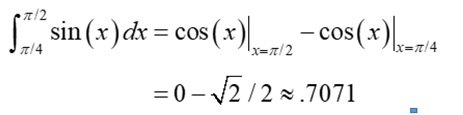

syms theta
res = int(sin(theta),[pi/4 pi/2])

$$res = \frac{\sqrt{2}}{2}$$

Some functions do not yield a useful analytical form under integration - i.e. MATLAB returns a solution in integral notation.

syms x
int(sin(sinh(x)), x)

$$ans = \int \sin\left(\sinh\left(x\right)\right)\mathrm{d}x$$

This highlights that some functions can only be **numerically integrated** (using numerical integration methods) or approximated using a Taylor expansion

#### Differential equations

Differential equations can be solved using the `dsolve` function. This function takes an input of symbolic variable corresponding to the differential equation to be solved.

**Solving first order ODEs. **The `diff` function (used for differentiating symbolic expressions) is used to create the differential equation.

clear
% Declare symbolic variables
syms y(t) a
% Define differential equation
eqn = diff(y,t) == a*y;
S = dsolve(eqn)

$$S = C_{1}\,{\mathrm{e}}^{a\,t}$$

**Note**: we **do not specify initial conditions** and so MATLAB produces a *general solution* to the ODE.

**Initial conditions **can be provided as a second input.

% Define initial conditions
cond = y(0) == 5;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 5\,{\mathrm{e}}^{a\,t}$$

**Second order ODEs** can be created by using the `diff` function and specifying the second order derivative.

% Define second order ODE. % Note the additional input to diff() to create
% a second order derivative.
eqn = diff(y,t,2) == a*y;
% Solve for general solution to differential equation
ySol(t) = dsolve(eqn)

$$ySol(t) = C_{1}\,{\mathrm{e}}^{-\sqrt{a}\,t}+C_{2}\,{\mathrm{e}}^{\sqrt{a}\,t}$$

% Specify initial conditions

% Define the first derivative so that it can be used as an initial
% condition
Dy = diff(y,t)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

syms b
% Define vector containing initial conditions
cond = [y(0)==b, Dy(0)==1];
% Solve for the specific form of the ODE solution
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = \frac{{\mathrm{e}}^{\sqrt{a}\,t}\,\left(\sqrt{a}\,b+1\right)}{2\,\sqrt{a}}+\frac{{\mathrm{e}}^{-\sqrt{a}\,t}\,\left(\sqrt{a}\,b-1\right)}{2\,\sqrt{a}}$$

**Solving sets of differential equations.** Explicit solutions to sets of ODEs can be solved by inputting a vector of ODEs into `dsolve`.

% Define ODEs
syms y(t) z(t)
% Define vector of ODEs
eqns = [diff(y,t) == z, diff(z,t) == -y];
% Find solution
S = dsolve(eqns);
S.z

$$ans = C_{2}\,\cos\left(t\right)-C_{1}\,\sin\left(t\right)$$

S.y

$$ans = C_{1}\,\cos\left(t\right)+C_{2}\,\sin\left(t\right)$$

Assigning initial conditions

S = dsolve(eqns,[y(0) == 1,z(0) == 0]);
S.z

$$ans = -\sin\left(t\right)$$

S.y

$$ans = \cos\left(t\right)$$

#### Example problem: Harmonic oscillator

Consider a 1 cm (radius) carbon ball in water that is attached to linear spring, which is attached to a surface, as shown below. Assuming $x\left(t\right)=0$ is the equilibrium position and the ball is pulled back to $x\left(0\right)=2\;\textrm{cm}$ and released, plot the $x$ position of the ball as a function of time for spring constants of  $k_1 ={10}^{-5} \;\frac{N}{m}\;\textrm{and}\;k_2 ={10}^{-6} \;\frac{N}{m}$.

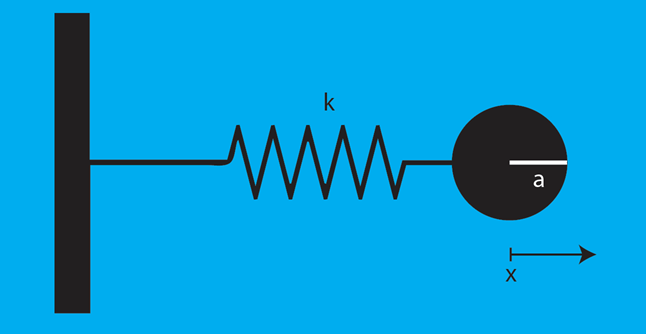

Consider only 1-D motion in the x direction, neglect any forces in the y-direction (*e.g.* related to gravity), and ignore mass of the spring.

**Step 1:** Write down what we know and determine the differential equation describing the system.

*Values that we know:*

- Radius of ball: $a=0\ldotp 01\;m$

- Density of carbon:  $\rho =2,260\;\frac{\textrm{kg}}{m^3 }$

- Viscosity of water:  $\eta ={10}^{-3} \;\textrm{Pa}\cdot s$

*Creating the differential equation:*

From our knowledge of **physics**, we know that the force exerted by a linear spring is directly proportional to the displacement of the spring. This corresponds to the well-known **Hooke's law**:

            
$$F_{\textrm{spring}} \left(t\right)=-\textrm{kx}\left(t\right)$$


From** fluid mechanics**, we know that the drag force exerted by a sphere in some fluid can be represented by **Stokes's law**. This relationship states that the drag force is directly proportional to the velocity of the sphere, the sphere's radius ($a$), and the viscosity of the fluid:

            
$$F_{\textrm{drag}} \left(t\right)=-6\pi a\eta v\left(t\right)=-6\pi a\eta \frac{\textrm{dx}}{\textrm{dt}}$$


From **Newton's second law of motion**, we can thus relate all forces acting on the object:

            
$$\textrm{ma}=m\frac{d^2 x}{{\textrm{dt}}^2 }=\rho \frac{4}{3}\pi a^3 \frac{d^2 x}{{\textrm{dt}}^2 }=\sum_i F_i \left(t\right)$$


Simplifying this differential equation:

            
$$\begin{array}{l}
\rho \frac{4}{3}\pi a^3 \frac{d^2 x}{{\textrm{dt}}^2 }\;+6\pi a\eta \frac{\textrm{dx}}{\textrm{dt}}+\textrm{kx}\left(t\right)=0\\
\frac{d^2 x}{{\textrm{dt}}^2 }\;+\frac{6\pi a\eta }{\rho \frac{4}{3}\pi a^3 }\frac{\textrm{dx}}{\textrm{dt}}+\frac{k}{\rho \frac{4}{3}\pi a^3 }x\left(t\right)=0
\end{array}$$


Or, by definining and substituting variables $b$ and $c$:

            
$$\frac{d^2 x}{{\textrm{dt}}^2 }\;+b\frac{\textrm{dx}}{\textrm{dt}}+\textrm{cx}\left(t\right)=0$$


**Step 2:** Convert the above to code

%Step 1: Setup
%write down parameters 

a = 0.01; % m
eta = 10^-3; % Pa*
rho = 2260;
k1 = 1*10^-5;
k2 = 1*10^-6;


%declare symbols 
%x(t): position of ball 
% b: coefficient in front of first derivative 
% c: coefficient in front of x(t)
syms x(t) b c k

%coeffiecent in front each derivative 
b = 6*sym(pi)*a*eta/(rho*4/3*sym(pi)*a/3);
c = k/(rho*4/3*sym(pi)*a^3);


**Step 3a: **solve differential equation for one value of k 

% Define first derivative of x 
Dx = diff(x,t);

eq = diff(Dx,t) + b*Dx +c*x == 0

$$eq(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\frac{27\,\frac{\partial }{\partial t}x\left(t\right)}{4520000}+\frac{37500\,k\,x\left(t\right)}{113\,\pi }=0$$

%substitute in one vale 
eq1 = subs(eq,k,k1)

$$eq1(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\frac{27\,\frac{\partial }{\partial t}x\left(t\right)}{4520000}+\frac{3\,x\left(t\right)}{904\,\pi }=0$$

sol1 = dsolve(eq1,[x(0) == 0.2, Dx(0) == 0])

$$sol1 = \frac{{\mathrm{e}}^{-\frac{27\,t}{9040000}}\,\cos\left(\frac{\sqrt{3}\,t\,\sqrt{90400000000-243\,\pi }}{9040000\,\sqrt{\pi }}\right)}{5}+\frac{9\,\sqrt{3}\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{27\,t}{9040000}}\,\sin\left(\frac{\sqrt{3}\,t\,\sqrt{90400000000-243\,\pi }}{9040000\,\sqrt{\pi }}\right)}{5\,\sqrt{90400000000-243\,\pi }}$$

**Step 3:** Solve the differential equation

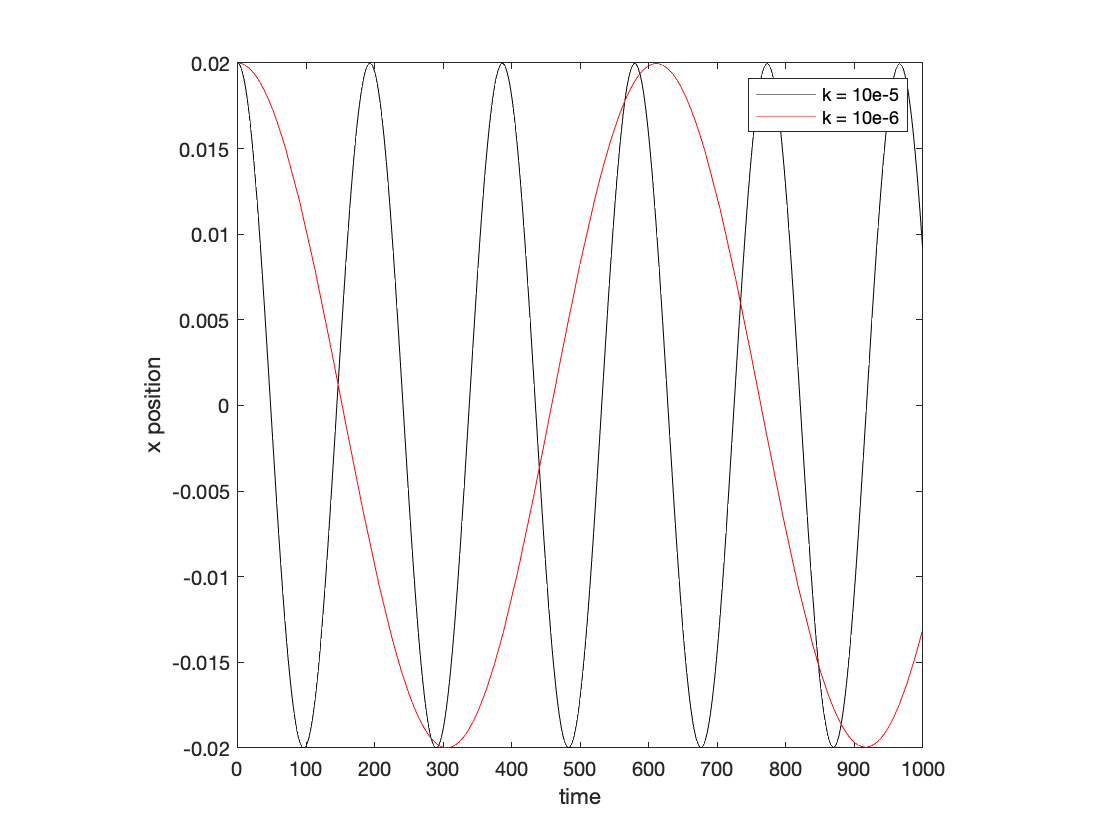

% Solve differential equation 
% IC: x(0) = 0.02
% IC: dx/dt(0) = 0 (the ball does not have any initial velocity
col = {'k','r'};
kval = [k1,k2];
for m = 1:2
    
    % Substitute in the variable
    eq1 = subs(eq,k,kval(m));
    
    % Solve the differential equation 
    sol1 = dsolve(eq1, [x(0) == 0.02, Dx(0) == 0]);
    
    % Plot the solution over time
    fplot(sol1,[0,1000],col{m});
    hold on
end

hold off
legend('k = 10e-5', 'k = 10e-6')
ylim([-0.02, 0.02])
axis square
ylabel('x position')
xlabel('time')

**Question**: how can we solve the above using `ode45`?

Start by **changing variables** to convert the higher order ODE into a set of first order ODEs.

        
$$\begin{array}{l}
\frac{d^2 x}{{\textrm{dt}}^2 }\;+b\frac{\textrm{dx}}{\textrm{dt}}+\textrm{cx}\left(t\right)=0\\
z_1 =x\\
z_2 =\frac{\textrm{dx}}{\textrm{dt}}\\
\frac{dz_2 }{\textrm{dt}}=-bz_2 -cz_1 \\
\frac{dz_1 }{\textrm{dt}}=z_2 
\end{array}$$


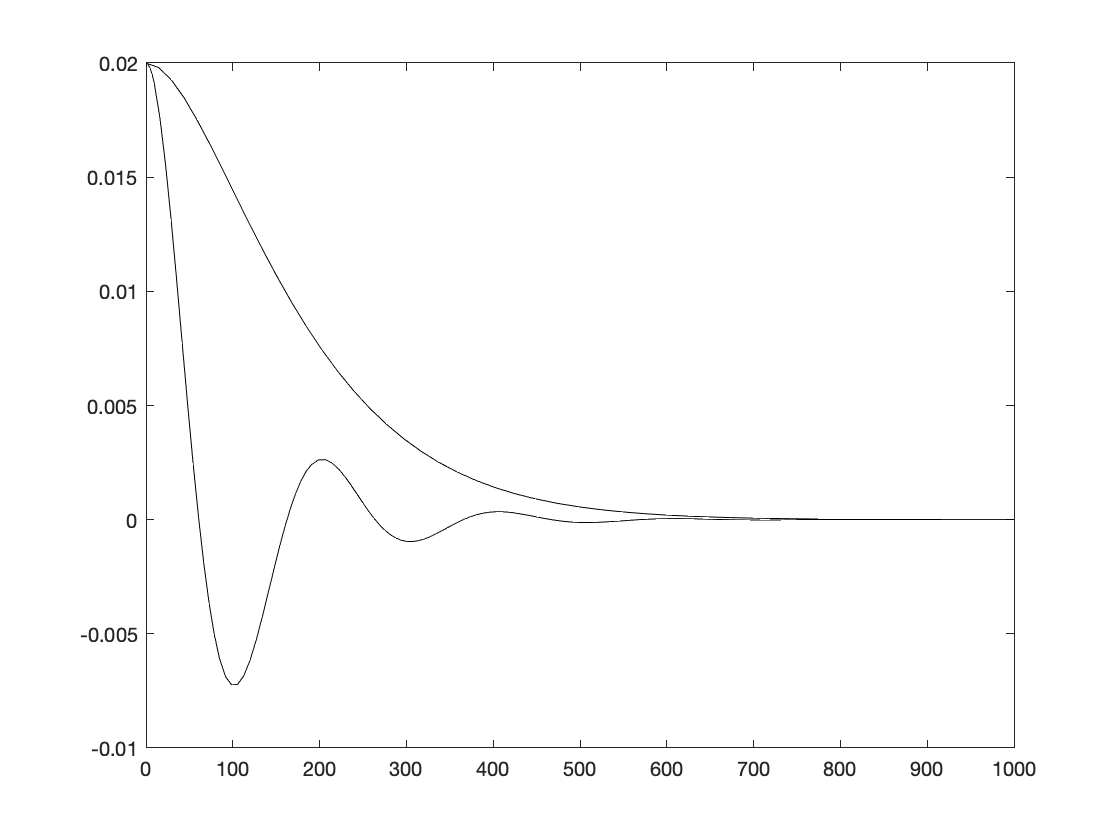

clear

% STEP 1: Setup
% Write down paramters describing the system

a = 0.01; % m
eta = 10^-3; % Pa*s
rho = 2260;
k1 = 1*10^-5;
k2 = 1*10^-6;

% Coefficient in front of each derivative
b = 6*(pi)*a*eta/(rho*4/3*(pi)*a^3);
c = [k1,k2]/(rho*4/3*(pi)*a^3);

for m = 1:2
    [t,out] = ode45(@springProblem,[0,1000],[0.02,0],[],b,c(m));
    
    plot(t,out(:,1),'k-')
    hold on
end
hold off

**Functions for Topic 24 are stored here:**

function F = eqnSet(x)
    % System of two non linear equations
    % F(1) and F(2): "equation" 1 and 2, respectively
    % x(1) and x(2): variable 1 and 2, respectively
    F(1) = x(2)-2*x(1)^2+3;
    F(2) = x(2)^2-x(1);
end

function dZdt = springProblem(t,z,b,c)

    dZdt = zeros(2,1);
    dZdt(1) = z(2); % z(1) = x
    dZdt(2) = -b*z(2) - c*z(1); % z(2) = dx/dt

end